clear all; close all; clc  %Declaraciones preeliminares
Run1='  ';                        %Identificador
Var1='U';                             %Variable a visualizar
Var2='T';
Var3='W';
Var4='HFX';

%%%% Para el primero %%%% 
    Ar1=['6'];
    Ar2=['6_2'];
    un = cat (3,squeeze(ncread(Ar1,Var1)),squeeze(ncread(Ar2,Var1)));
    t = cat (3,squeeze(ncread(Ar1,Var2))+100,squeeze(ncread(Ar2,Var2))+100);
    wn = cat (3,squeeze(ncread(Ar1,Var3)),squeeze(ncread(Ar2,Var3)));
    HFX= cat (2,squeeze(ncread(Ar1,Var4)),squeeze(ncread(Ar2,Var4)));
    puntosz=99;                           %Tamaño Vertical de malla
    gravedad=1.352;
    %G=5;  %Numero de niveles
    PHB1=ncread(Ar1,'PHB');
    PHB=squeeze(PHB1);
    clear PHB1
    PH1=ncread(Ar1,'PH');
    PH=squeeze(PH1);
    clear PH1
    gz=PHB+PH;
    clear PHB1 PHB PH
    gz2d=mean(gz,3,"omitmissing");
    ejez2=mean(gz2d)./(gravedad);
    un(:,:,37)=[];
    t(:,:,37)=[];
    wn(:,:,37)=[];
    HFX(:,37)=[];
    un(:,:,37)=[];
    t(:,:,37)=[];
    wn(:,:,37)=[];
    HFX(:,37)=[];
    for i=1:1:puntosz
        ejez(i)=(ejez2(i)+ejez2(i+1))/2;
    end
    clear gz2d gz
    for i=1:1:length(wn(:,1,1)) 
        u(i,:,:)=(un(i,:,:)+un(i+1,:,:))./2;
    end
    for i=1:1:puntosz
        w(:,i,:)=(wn(:,i,:)+wn(:,i+1,:))./2;
    end
    u(:,:,1)=[];
    t(:,:,1)=[];
    w(:,:,1)=[];
    u(:,:,59)=[];
    t(:,:,59)=[];
    w(:,:,59)=[];
    u(:,:,58)=[];
    t(:,:,58)=[];
    w(:,:,58)=[];
    puntosx=501;
wind=sqrt((u.^2)+(w.^2));
uprom = mean(u,1);                 %Promedio en X
uprom = repmat(uprom,puntosx-1,1);       %Creamos una matriz con el vector resultante
uprim = u-uprom;                  %Obtenemos la fluctuacion 
tprom = mean(t,1);
tprom = repmat(tprom,puntosx-1,1);
tprim = t-tprom;
wprom = mean(w,1);
wprom = repmat(wprom,puntosx-1,1);
wprim = w-wprom;
windprom=mean(wind,1);
windprom=repmat(windprom,puntosx-1,1);
windprim=wind-windprom;
uu=uprim.*uprim;
uuprom=mean(uu,1);
uu = repmat(uuprom,puntosx-1,1);
clear uuprom


for p=1:1:(57/3)-2;
       i=(3*p-2);
       proUprom(:,:,p)=squeeze(mean(u(:,:,i:i+2),3));
       varUprom(:,:,p)=squeeze(rms(u(:,:,i:i+2),3));
       proUprim(:,:,p)=squeeze(mean(uprim(:,:,i:i+2),3));
       varUprim(:,:,p)=squeeze(rms(uprim(:,:,i:i+2),3));
       proTprom(:,:,p)=squeeze(mean(t(:,:,i:i+2),3));
       varTprom(:,:,p)=squeeze(rms(t(:,:,i:i+2),3));
       proTprim(:,:,p)=squeeze(mean(tprim(:,:,i:i+2),3));
       varTprim(:,:,p)=squeeze(rms(tprim(:,:,i:i+2),3));
       proWprom(:,:,p)=squeeze(mean(w(:,:,i:i+2),3));
       varWprom(:,:,p)=squeeze(rms(w(:,:,i:i+2),3));
       proWprim(:,:,p)=squeeze(mean(wprim(:,:,i:i+2),3));
       varWprim(:,:,p)=squeeze(rms(wprim(:,:,i:i+2),3));
       % proRi(:,:,p)=squeeze(mean(Ri(:,:,i:i+5),3));
       % varRi(:,:,p)=squeeze(rms(Ri(:,:,i:i+5),3));
       proUUprim(:,:,p)=squeeze(mean(uu(:,:,i:i+2),3));
       varUUprim(:,:,p)=squeeze(rms(uu(:,:,i:i+2),3));
       proHprom(:,:,p)=5940.*squeeze(mean((wprim(:,:,i:i+2).*tprim(:,:,i:i+2)),3));
       varHprom(:,:,p)=5940.*squeeze(rms((wprim(:,:,i:i+2).*tprim(:,:,i:i+2)),3));
       j=p;
end 
for i=1:1:j
       perUpro(:,i)=squeeze(mean(proUprom(:,:,i),1));
       perUvar(:,i)=squeeze(rms(varUprim(:,:,i),1));
       perTpro(:,i)=squeeze(mean(proTprom(:,:,i),1));
       perTvar(:,i)=squeeze(rms(varTprim(:,:,i),1));
       perWpro(:,i)=squeeze(mean(proWprom(:,:,i),1));
       perWvar(:,i)=squeeze(rms(varWprim(:,:,i),1));
       perHpro(:,i)=squeeze(mean(proHprom(:,:,i),1));
       perHvar(:,i)=squeeze(rms(varHprom(:,:,i),1));
       % perRpro(:,i)=squeeze(mean(proRi(:,:,i),1));
       % perRvar(:,i)=squeeze(rms(varRi(:,:,i),1));
       perUUvar(:,i)=squeeze(rms(varUUprim(:,:,i),1));
       perUUpro(:,i)=squeeze(mean(proUUprim(:,:,i),1));
end


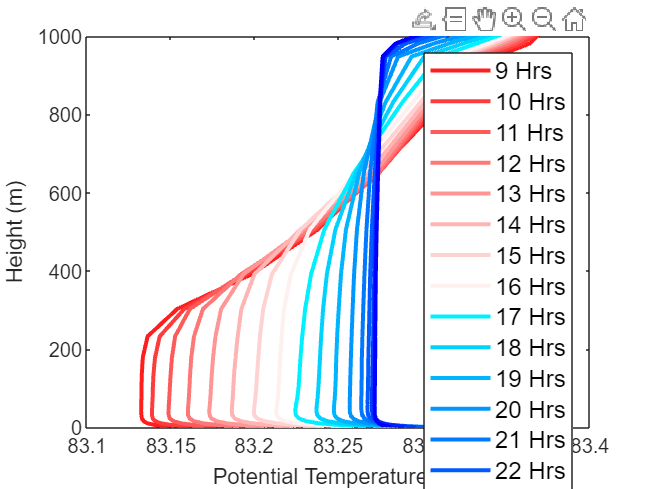

G=17;  %Numero de niveles
for i=1:1:G
    if i<=G/2
        r(i)=1;
        g(i)=i*2/G;
        b(i)=i*2/G;
    else 
        r(i)=0;
        g(i)=(G-i)*2/G;
        b(i)=1;
    end 
end 
colors_p=[r; g; b]';

for i=1:1:17
    plot(perTpro(:,i),ejez,'DisplayName',strcat(string(i+8),' Hrs'),'LineWidth',2);
    ylim([0 1000]);
    % xlim([83.0 83.55]);
    ax = gca; 
    ax.ColorOrder = colors_p;
    % ax.Color = 'c';
    ylabel('Height (m)')
    xlabel('Potential Temperature (K)')
    % title('Velocity (mean U)')
    legend('-DynamicLegend',"AutoUpdate","on",'Location','northeast','FontSize',12);
    % saveas(gca,'Tprom.png');
    hold on
end 
hold off